# Simulación de una planta solar gas tipo túnel para la deshidratación de productos agroindustriales

## "Modelo simplificado" 

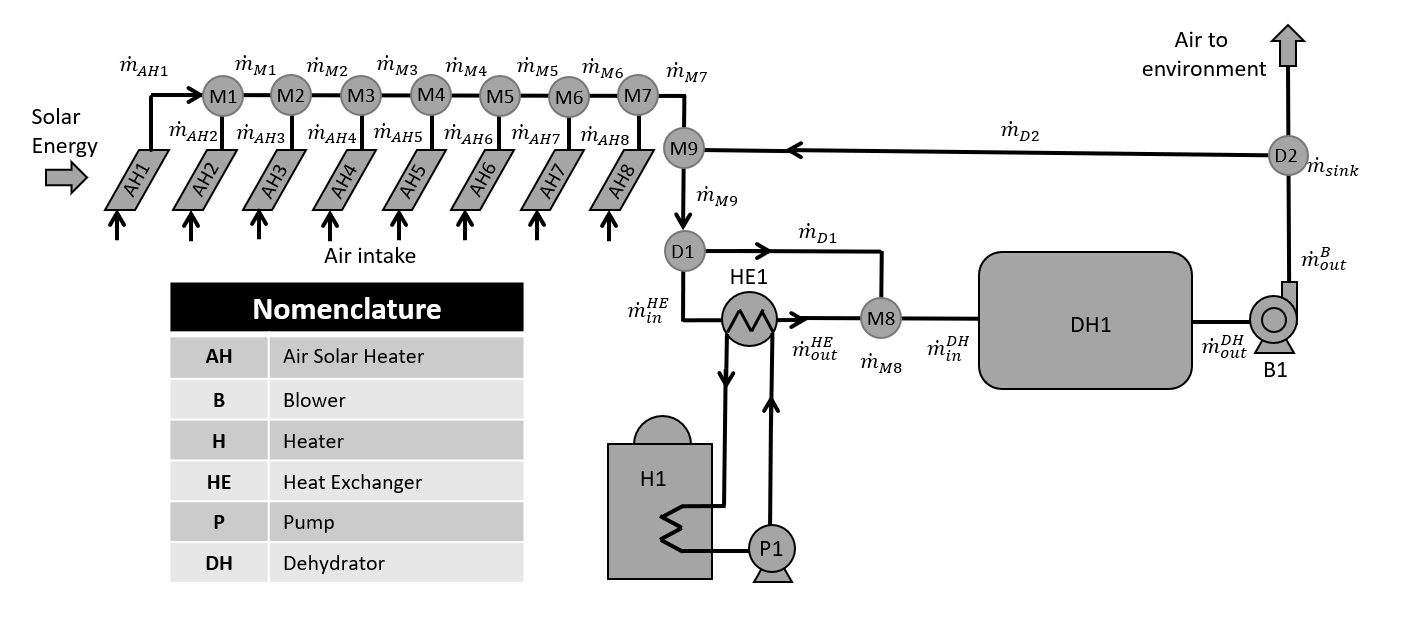    


function [Q_aux_tot, dry_time, M_prod_fin, MR_fin, Irradiacion]=opt_tunel_mod2(m_max,T_min,r_div2,t_rec_ini, W0, m_i, Mi, mwi, md, m_f, Mf, mwf, M_des)
%function [Q_aux_tot, dry_time, M_prod_fin, MR_fin, Irradiacion]=opt_tunel_mod2(m_max, T_min, W0, m_i, Mi, mwi, md, m_f, Mf, mwf, M_des)

%global W0 m_i Mi mwi md m_f Mf mwf M_des A_sec t_ini t_step P_amb LT_AH md
global  A_sec t_step P_amb

## Variables de entrada

t_max=20; % "Tiempo de experimentación [h]"
t_rec_ini=t_rec_ini*3600;%3*3600; %Tiempo de inicio de recirculación [h]
t_rec_fin=40*3600; %Tiempo de fin de recirculación [h]
r_div1=0/100; % Relación de división en D1
%r_div2=0/100; % Relación de división en D2 (recirculación)
Q_perd_ducto=10/100; % Porcentaje de pérdidas en ducto de recirculación
%m_max=0.11; % 0.39;%0.19=0.5;%0.115=0.3;%0.043=0.12;% "Flujo másico de aire en el captador AH8[kg/s]"
%T_min=40; %Temperatura mínima antes de M9 [°C]
A_sec=2.25; % "Área de sección transversal de entrada al túnel [m^2]"
t_ini=0; %tiempo inicial
t_step=0.1; % paso de tiempo
cond_amb="10jun21_real";
calor_aux=true;
etha_capt="constante";%eficiencia ce captación
LT_AH=65; %Límite de temperatura en AH
T_ini=25; %Temperatura de inicio en Gabinetes, producto y aire

## Cálculos de humedad


$$\mathit{\mathbf{M}}=\frac{\mathit{\mathbf{m}}}{1-\mathit{\mathbf{m}}}$$
 

siendo:


$$M=\textrm{Contenido}\;\textrm{de}\;\textrm{humedad}\;\left(\textrm{bs}\right)$$



$$m=\textrm{contenido}\;\textrm{de}\;\textrm{humedad}\left(\textrm{bh}\right)$$



$${\mathit{\mathbf{m}}}_{\mathit{\mathbf{w}}} =\mathit{\mathbf{W}}*\mathit{\mathbf{m}}$$
 

siendo:


$$m_w =\textrm{masa}\;\textrm{de}\;\textrm{agua}\;\left\lbrack \textrm{kg}\right\rbrack$$



$$W=\textrm{Peso}\;\textrm{de}\;\textrm{producto}$$



$${\mathit{\mathbf{m}}}_{\mathit{\mathbf{d}}} =\frac{{\mathit{\mathbf{m}}}_{\mathit{\mathbf{w}}} }{\mathit{\mathbf{M}}}$$


siendo:


$$m_{d\;} =\textrm{masa}\;\textrm{de}\;\textrm{producto}\;\textrm{seco}\;\left\lbrack \textrm{kg}\right\rbrack$$


## Pre-alojamiento de datos

tiempo=t_ini:t_step:t_max;
long1=size(tiempo);
mat=zeros(long1(1,2),1);

[t,T_amb,P_amb,HR_amb,I,E_capt,m_AH8,m_AH7,m_AH6,m_AH5,m_AH4,m_AH3,m_AH2,m_AH1,w_amb, h_ent,...
    m_M1,h_AH1,h_AH2,h_M1,T_AH1,T_AH2,T_M1,m_M2,h_AH3,h_M2,T_AH3,T_M2,m_M3, h_AH4,h_M3,T_AH4,...
    T_M3,m_M4,h_AH5,h_M4,T_AH5,T_M4,m_M5,h_AH6,h_M5,T_AH6,T_M5, m_M6,h_AH7, h_M6,T_AH7,T_M6,...
    m_M7,h_AH8,h_M7,w_M7,T_AH8,T_M7, HR_M7,m_D1,m_HE1,h_D1,T_D1,w_D1,h_HE1_in, T_HE1_in,...
    m_HE1_in, m_HE1_out, Q_aux,T_HE1_out,h_HE1_out,w_HE1_in,m_M8,w_M8,h_M8,T_M8,T_M9,h_M9,m_M9,w_M9,m_D2,...
    m_DH_in, w_DH_in,h_D2,h_DH_in,T_DH_in,HR_DH_in,v_DH_in,k,m_agua,mw_vap,mw_DH_in,mw_DH_out,...
    m_DH_out,w_DH_out,Tw_vap,hw_vap, h_DH_out,T_DH_out,w_D2,HR_DH_out,w_sink,T_D2,m_sink,T_sink,...
    M_prod,T_prod,T_gab,MR]=preallocating(mat);

i=1;j=1;

## Ciclo principal

%for rec_max=0:0.2:0.8
M_prod(i)=Mi;

for tiempo=t_ini:t_step:t_max

    t(i)=tiempo*3600;

###  "Variables de ambientales"

    P_amb=89.3;% "Presión ambiente [kPa]"
    %if strcmp(cond_amb,"constante")
    T_amb(i)=25; % "Temperatura ambiente [°C]"
    HR_amb(i)=0.6;% "Humedad Relativa"
    I(i)=0;  % "Irradiancia [W/m^2]"
    %end

    %     if tiempo>4.5 && strcmp(cond_amb,"variable")
    %         T_amb(i)=T_amb(i); % "Temperatura ambiente [°C]"
    %         HR_amb(i)=HR_amb(i);% "Humedad Relativa"
    %         I(i)=I(i);  % "Irradiancia [W/m^2]"
    %     end
    if strcmp(cond_amb,"variable")
        T_amb(i)=1.6031*tiempo+25.204; % "Temperatura ambiente [°C]"
        HR_amb(i)=(0.5356*tiempo^3-2.9126*tiempo^2-2.6044*tiempo+59.539)/100; % "Humedad Relativa"
        I(i)=-36.085*tiempo^2+207.22*tiempo+631.33;  % "Irradiancia [W/m^2]"
    end
    if strcmp(cond_amb,"10jun21")
        T_amb(i)=9.7152e-04*tiempo^4-0.0304*tiempo^3+0.2914*tiempo^2-0.2138*tiempo+23.9443; % "Temperatura ambiente [°C]"
        HR_amb(i)=(-0.0019*tiempo^4+0.1245*tiempo^3-1.3295*tiempo^2-1.9212*tiempo+87.5956)/100; % "Humedad Relativa"
        I(i)=0.5125*tiempo^4-12.0790*tiempo^3+66.4485*tiempo^2+44.4091*tiempo+146.7760;  % "Irradiancia [W/m^2]"
    end
    if strcmp(cond_amb,"10jun21_real")

        if tiempo==t_ini

            data=load('Mapeo4_temp100621.txt');
            t_real=data(:,1);
            T_amb_real=data(:,72); % Temperatura ambiente
            I_amb_real=data(:,75); %Irradiancia
            HR_amb_real=data(:,65); %Humedad relativa ambiente

            r=1;

        end

        t_busc=tiempo;

        while t_real(r)<=t_busc
            t_ant=r;
            t_post=r+2;
            r=r+1;
        end

        mI=(I_amb_real(t_post)-I_amb_real(t_ant))/(t_real(t_post)-t_real(t_ant));
        bI=I_amb_real(t_post)-mI*t_real(t_post);
        I_busc=mI*t_busc+bI;

        mT=(T_amb_real(t_post)-T_amb_real(t_ant))/(t_real(t_post)-t_real(t_ant));
        bT=T_amb_real(t_post)-mT*t_real(t_post);
        T_busc=mT*t_busc+bT;

        mHR=(HR_amb_real(t_post)-HR_amb_real(t_ant))/(t_real(t_post)-t_real(t_ant));
        bHR=HR_amb_real(t_post)-mHR*t_real(t_post);
        HR_busc=mHR*t_busc+bHR;

        T_amb(i)=T_busc; % "Temperatura ambiente [°C]"
        HR_amb(i)=HR_busc/100; % "Humedad Relativa"
        I(i)=I_busc; % "Irradiancia [W/m^2]"

    end


###    "Cálculo de energía en captadores" 

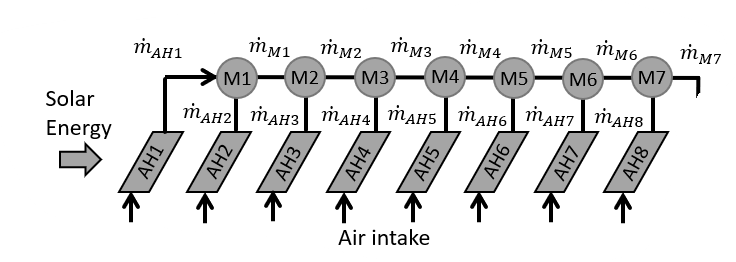


$${\mathit{\mathbf{E}}}_{\textrm{AHn}} =\eta_{\textrm{AHn}} {\;\mathit{\mathbf{A}}}_{\textrm{capt}} \;{\mathit{\mathbf{I}}}_{\textrm{amb}}$$


siendo:


$$\begin{array}{l}
\eta_{\textrm{AHn}} =\textrm{eficiencia}\;\textrm{de}\;\textrm{captación}\;\left\lbrack %\right\rbrack \\
A_{\textrm{capt}} =\textrm{Área}\;\textrm{de}\;\textrm{captación}\;\left\lbrack m^2 \right\rbrack \\
I_{\textrm{amb}} \;=\textrm{Irradiancia}\;\left\lbrack \frac{W}{m^2 }\right\rbrack 
\end{array}$$


    I(i)=0;
    serie=2; % "Número de colectores en serie"
    A_cap=2.5*serie; % "[m2] Área de captación por bateria"
    if strcmp(etha_capt,"variable")
        P=3.9;
        G=I(i)*1000;
        ETHA_capt(i)=0.656-3.48050*(P/G)-0.02380*(P^2/G);
    else
        ETHA_capt(i)=50/100; % "Eficiencia"
    end
    E_capt(i)=I(i)*A_cap*ETHA_capt(i)/1000; % "Energía captada"

####    "Flujos másicos por captador"


$${\overset{*}{\mathit{\mathbf{m}}} }_{\textrm{AHn}-1} ={\overset{*}{\mathit{\mathbf{m}}} }_{\textrm{AHn}} \;{\;\mathit{\mathbf{f}}}_{\textrm{perd}}$$


siendo:


$$f_{\textrm{perd}} =\textrm{factor}\;\textrm{de}\;\textrm{pérdida}\;\textrm{de}\;\textrm{flujo}\;\textrm{por}\;\textrm{presión}$$


    f_per=0.975;
    if t(i)>t_rec_ini && t(i)<t_rec_fin
        m_AH8(i)=m_max*(1-r_div2);
        if i==1
            m_AH8(i)=m_max;
        end
    else
        m_AH8(i)=m_max; % "*(1-rec_max)" "[kg/s] Flujo másico del captador 8"
    end
    m_AH7(i)=m_AH8(i)*f_per; %"Flujo másico  del captador 7 [kg/s]"
    m_AH6(i)=m_AH7(i)*f_per; %"Flujo másico del captador 6 [kg/s]"
    m_AH5(i)=m_AH6(i)*f_per; %"Flujo másico del captador 5 [kg/s]"
    m_AH4(i)=m_AH5(i)*f_per;  %"Flujo másico del captador 4 [kg/s]"
    m_AH3(i)=m_AH4(i)*f_per; %"Flujo másico del captador 3 [kg/s]"
    m_AH2(i)=m_AH3(i)*f_per; %"Flujo másico del captador 2 [kg/s]"
    m_AH1(i)=m_AH2(i)*f_per; %"Flujo másico del captador 1 [kg/s]"

####     "Cálculo de propiedades termodinámicas de entrada en el captador"

    w_amb(i)=humrat_AirH2O(T_amb(i),P_amb,HR_amb(i)); %Humedad específica ambiente [kg_agua/kg_aire]
    h_ent(i)=enthalpy_AirH2O(T_amb(i),P_amb,HR_amb(i)); %Entalpía de entrada [kJ/kg]

### "Balance de materia y energía mezclador 1"

${\overset{*}{m} }_{\textrm{M1}} ={\overset{*}{m} }_{\textrm{AH1}} +{\overset{*}{m} }_{\textrm{AH2}}$ (masa)

${\overset{*}{m} }_{\textrm{M1}\;} h_{\textrm{M1}} ={\overset{*}{m} }_{\textrm{AH1}} {\;h}_{\textrm{AH1}} +{\overset{*}{m} }_{\textrm{AH2}} {\;h}_{\textrm{AH2}}$ (energía)


$$h_{\textrm{AHn}} =\frac{E_{\textrm{AHn}} }{{\overset{*}{m} }_{\textrm{AH1}} \;}+h_{\textrm{ent}}$$


    m_M1(i)=m_AH1(i)+m_AH2(i); % Flujo másico en M1 [kg/s]
    h_AH1(i)=E_capt(i)/m_AH1(i)+h_ent(i); % Entalpía de salida en AH1 [kJ/kg]
    h_AH2(i)=E_capt(i)/m_AH2(i)+h_ent(i); % Entalpía de salida en AH2 [kJ/kg]
    h_M1(i)=((m_AH1(i)*h_AH1(i))+(m_AH2(i)*h_AH2(i)))/m_M1(i); % Entalpía de salida en M1 [kJ/kg]
    T_AH1(i)=temperature_AirH2O(h_AH1(i),P_amb,w_amb(i)); % Temperatura de salida en AH1 [°C]
    T_AH2(i)=temperature_AirH2O(h_AH2(i),P_amb,w_amb(i)); % Temperatura de salida en AH2 [°C]
    T_M1(i)=temperature_AirH2O(h_M1(i),P_amb,w_amb(i)); % Temperatura de salida en M1 [°C]

###  "Balance de materia y energía mezclador 2"

    m_M2(i)=m_M1(i)+m_AH3(i); % Flujo másico en M2 [kg/s]
    h_AH3(i)=E_capt(i)/m_AH3(i)+h_ent(i); % Entalpía de salida en AH3 [kJ/kg]
    h_M2(i)=((m_M1(i)*h_M1(i))+(m_AH3(i)*h_AH3(i)))/m_M2(i); % Entalpía de salida en M2 [kJ/kg]
    T_AH3(i)=temperature_AirH2O(h_AH3(i),P_amb,w_amb(i)); % Temperatura de salida en AH3 [°C]
    T_M2(i)=temperature_AirH2O(h_M2(i),P_amb,w_amb(i)); % Temperatura de salida en M2 [°C]

### "Balance de materia y energía mezclador 3"

    m_M3(i)=m_M2(i)+m_AH4(i); % Flujo másico en M3 [kg/s]
    h_AH4(i)=E_capt(i)/m_AH4(i)+h_ent(i); % Entalpía de salida en AH4 [kJ/kg]
    h_M3(i)=((m_M2(i)*h_M2(i))+(m_AH4(i)*h_AH4(i)))/m_M3(i); % Entalpía de salida en M3 [kJ/kg]
    T_AH4(i)=temperature_AirH2O(h_AH4(i),P_amb,w_amb(i)); % Temperatura de salida en AH4 [°C]
    T_M3(i)=temperature_AirH2O(h_M3(i),P_amb,w_amb(i)); % Temperatura de salida en M3 [°C]

### "Balance de materia y energía mezclador 4"

    m_M4(i)=m_M3(i)+m_AH5(i); % Flujo másico en M3 [kg/s]
    h_AH5(i)=E_capt(i)/m_AH5(i)+h_ent(i); % Entalpía de salida en AH5 [kJ/kg]
    h_M4(i)=((m_M3(i)*h_M3(i))+(m_AH5(i)*h_AH5(i)))/m_M4(i); % Entalpía de salida en M4 [kJ/kg]
    T_AH5(i)=temperature_AirH2O(h_AH5(i),P_amb,w_amb(i)); % Temperatura de salida en AH5 [°C]
    T_M4(i)=temperature_AirH2O(h_M4(i),P_amb,w_amb(i)); % Temperatura de salida en M4 [°C]

### "Balance de materia y energía mezclador 5"

    m_M5(i)=m_M4(i)+m_AH6(i); % Flujo másico en M5 [kg/s]
    h_AH6(i)=E_capt(i)/m_AH6(i)+h_ent(i); % Entalpía de salida en AH6 [kJ/kg]
    h_M5(i)=((m_M4(i)*h_M4(i))+(m_AH6(i)*h_AH6(i)))/m_M5(i); % Entalpía de salida en M5 [kJ/kg]
    T_AH6(i)=temperature_AirH2O(h_AH6(i),P_amb,w_amb(i)); % Temperatura de salida en AH6 [°C]
    T_M5(i)=temperature_AirH2O(h_M5(i),P_amb,w_amb(i)); % Temperatura de salida en M5 [°C]

### "Balance de materia y energía mezclador 6"

    m_M6(i)=m_M5(i)+m_AH7(i); % Flujo másico en M6 [kg/s]
    h_AH7(i)=E_capt(i)/m_AH7(i)+h_ent(i); % Entalpía de salida en AH7 [kJ/kg]
    h_M6(i)=((m_M5(i)*h_M5(i))+(m_AH7(i)*h_AH7(i)))/m_M6(i); % Entalpía de salida en M6 [kJ/kg]
    T_AH7(i)=temperature_AirH2O(h_AH7(i),P_amb,w_amb(i)); % Temperatura de salida en AH7 [°C]
    T_M6(i)=temperature_AirH2O(h_M6(i),P_amb,w_amb(i)); % Temperatura de salida en M6 [°C]

### "Balance de materia y energía mezclador 7"

    m_M7(i)=m_M6(i)+m_AH8(i); % Flujo másico en M7 [kg/s]
    h_AH8(i)=E_capt(i)/m_AH8(i)+h_ent(i); % Entalpía de salida en AH8 [kJ/kg]
    h_M7(i)=((m_M6(i)*h_M6(i))+(m_AH8(i)*h_AH8(i)))/m_M7(i); % Entalpía de salida en M7 [kJ/kg]
    w_M7=w_amb; %humedad específica en M7 [kg_agua/kg/_aire]
    T_AH8(i)=temperature_AirH2O(h_AH8(i),P_amb,w_amb(i)); % Temperatura de salida en AH8 [°C]
    T_M7(i)=temperature_AirH2O(h_M7(i),P_amb,w_amb(i)); % Temperatura de salida en M7 [°C]
    HR_M7(i)=relhum_AirH2O(T_M7(i),w_amb(i),P_amb); %Humedad relativa en M7

    if T_M7(i)>=LT_AH %Límite de temperatura en mezclador 7
        T_M7(i)=LT_AH;
        HR_M7(i)=relhum_AirH2O(T_M7(i),w_M7(i),P_amb);
        h_M7(i)=enthalpy_AirH2O(T_M7(i),P_amb,HR_M7(i));
    end
    if t(i)>t_rec_ini && t(i)<t_rec_fin
        if r_div2==1 && i>=2
            [m_AH8,m_AH7,m_AH6,m_AH5,m_AH4,...
                m_AH3,m_AH2,m_AH1,w_amb,h_ent,m_M1,h_AH1,h_AH2,h_M1,T_AH1,...
                T_AH2,T_M1,m_M2,h_AH3,h_M2,T_AH3,T_M2,m_M3,h_AH4,h_M3,T_AH4,...
                T_M3,m_M4,h_AH5,h_M4,T_AH5,T_M4,m_M5,h_AH6,h_M5,T_AH6,T_M5,...
                m_M6,h_AH7,h_M6,T_AH7,T_M6,m_M7,h_AH8,h_M7,w_M7,T_AH8,T_M7,...
                HR_M7]=ceros_rec1(i);
        end
    end

### "Balance de materia y energía en el Mezclador 9"

    if t(i)>t_rec_ini && t(i)<t_rec_fin
        m_D2(i)=m_D2(i-1);
        h_D2(i)=h_D2(i-1)*(1-Q_perd_ducto);
        w_D2(i)=w_D2(i-1);
    else
        m_D2(i)=0;
        h_D2(i)=0;
        w_D2(i)=0;
    end

    m_M9(i)=m_M7(i)+m_D2(i); % "flujo másico de salida de M9 [kg/s] "
    h_M9(i)=(m_M7(i)*h_M7(i)+m_D2(i)*h_D2(i))/m_M9(i); % Entalpía de salida de M9 [kJ/kg]
    w_M9(i)=(m_M7(i)*w_M7(i)+m_D2(i)*w_D2(i))/(m_M9(i)); % Humedad específica de salida de M9 [kg_agua/kg_aire]
    T_M9(i)=temperature_AirH2O(h_M9(i),P_amb,w_M9(i)); %Temperatura de salida en M9 [°C]

### "Balance de materia y energía en el divisor 1"

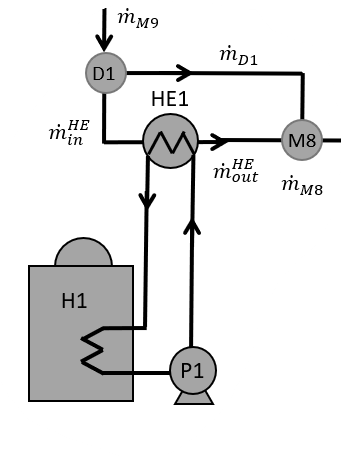

    m_D1(i)=m_M9(i)*r_div1; % "FLujo másico de salida de D1 [kg/s]"
    h_D1(i)=h_M9(i); % entalía en D1[kJ/kg]
    w_D1(i)=w_M9(i); % Humedad específica en D1 [kg_agua/kg_aire]
    T_D1(i)=T_M9(i); % Temperatura en D1 [°C]

###     "Balance de materia y energía en el Intercambiador"

    m_HE1_in(i)=m_M9(i)*(1-r_div1); % "corriente de salida del divisor 1 pasando al intercambiador de calor"
    w_HE1_in(i)=w_M9(i); %Humedad específica de entrada en HE1 [kg_agua/kg_aire]
    T_HE1_in(i)=T_M9(i); %Temperatura de entrada a HE1 [°C]
    h_HE1_in(i)=h_M9(i);

    %Cálculo del calor auxiliar
    if T_HE1_in(i)>T_min
        Q_aux(i)=0;
        T_HE1_out(i)=T_HE1_in(i);
        h_HE1_out(i)=h_HE1_in(i);
    else
        if calor_aux ==1
            h_HE1_out(i)=enthalpy_AirH2O(T_min,P_amb,relhum_AirH2O(T_min,w_HE1_in(i),P_amb));
            Q_aux(i)=m_HE1_in(i)*(h_HE1_out(i)-h_HE1_in(i));
            T_HE1_out(i)=T_min; %temperature_AirH2O(h_HE1_out(i),P_amb,w_amb(i));
        end
        if calor_aux ==0
            Q_aux(i)=0;
            T_HE1_out(i)=T_HE1_in(i);
            h_HE1_out(i)=h_HE1_in(i);
        end
    end
    m_HE1_out(i)=m_HE1_in(i);

### "Balance de materia y energía en el Mezclador 8"

    m_M8(i)=m_D1(i)+m_HE1_out(i); %Flujo másico en M8 [kg/s]
    w_M8(i)=w_M9(i); %Humedad específica en M8 [kg_agua/kg_aire]
    h_M8(i)=(m_D1(i)*h_D1(i)+m_HE1_out(i)*h_HE1_out(i))/m_M8(i); %Entalpía en M8 [kJ/kg]
    T_M8(i)=temperature_AirH2O(h_M8(i),P_amb,w_M8(i)); %Temperatura en M8 [°C]

### "Balance de materia y energía en túnel"

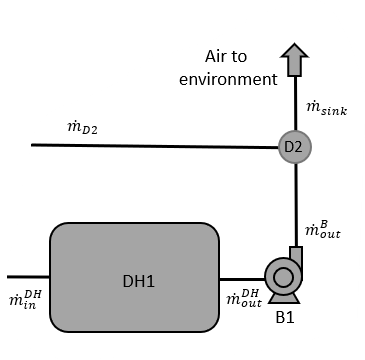

    T_DH_in(i)=T_M8(i); %Temperatura de entrada al túnel [°C]
    m_DH_in(i)=m_M8(i); %Flujo de masa de entrada de aire seco al túnel
    m_DH_out(i)=m_DH_in(i); %Flujo másico de salida de aire seco al túnel
    w_DH_in(i)=w_M8(i); %Humedad específica de entrada al túnel [kg_agua/kg_aire]
    HR_DH_in(i)=relhum_AirH2O(T_DH_in(i),w_DH_in(i),P_amb); %Humedad relativa de entrada al túnel

    if tiempo==t_ini %Establecimiento de condiciones iniciales
        T_prod(i)=T_ini;
        T_gab(i)=T_ini;
        T_DH_out(i)=T_ini;
        mw_vap(i)=0;
        w_DH_out(i)=0;
        MR(1)=1;

    end
    %     if T_DH_in(i)>T_M7(i)
    %
    %         T_DH_in(i)=T_M7(i);
    %     end
    %     if t(i)==20*3600
    %         i=i;
    %     end

    [M_prod(i+1),T_DH_out(i+1),T_prod(i+1),T_gab(i+1),mw_vap(i),FV_DH_in(i),v_DH_in(i),Twb(i)]=tunel_mod2(m_DH_in(i),w_DH_in(i),T_DH_in(i),T_prod(i),T_gab(i),tiempo,A_sec,M_prod(i),h_ent(i),w_amb(i),Mf,md,mwi,t_ini);

    %     if T_DH_out(i+1)>T_M7(i)
    %         T_DH_out(i+1)=T_M7(i);
    %     end

    
    if M_prod(i+1)<M_des*.3
        M_prod(i+1)=M_des*.3;
    end

    w_DH_out(i)=(m_DH_in(i)*w_DH_in(i)+mw_vap(i))/m_DH_out(i); %Humedad específica a la salida del túnel [kg_agua/kg/aire]
    HR_DH_out(i)=relhum_AirH2O(T_DH_out(i),w_DH_out(i),P_amb); %Humedad relativa a la salida del túnel
    h_DH_out(i)=enthalpy_AirH2O(T_DH_out(i),P_amb,HR_DH_out(i)); %Entalpía a la salida del túnel [kJ/kg]


    MR(i+1)=(M_prod(i+1)-Mf)/(Mi-Mf);
    %MR(i+1)=(M_prod(i+1)-Me)/(Mi_Me);



### "Balance de materia y energía en el divisor 2"

    if t(i) >= t_rec_ini && t(i) <= t_rec_fin
        m_D2(i)=m_DH_out(i)*r_div2; %Flujo de masa en D2
        w_D2(i)=w_DH_out(i); %Humedad específica en D2
        h_D2(i)= h_DH_out(i); %Entalpía en D2
        T_D2(i)=temperature_AirH2O(h_D2(i),P_amb,w_D2(i)); %Temperatura en D2 [°C]
    end

### "Balance de materia y energía en salida

    if t(i) >= t_rec_ini && t(i) <= t_rec_fin
        m_sink(i) = m_DH_out(i) * (1-r_div2); % "Masa de aire seco a la salida del ciclo"
    else
        m_sink(i) = m_DH_out(i);
    end

    w_sink(i) = w_DH_out(i); % "Humedad específica a la salida del ciclo"
    HR_sink = HR_DH_out(i); % "Humedad relativa a la salida del ciclo"
    T_sink(i)=T_DH_out(i); %"Temperatura de aire  a la salida del ciclo"

    %Cálculos adicionales
    if M_prod(i)<=M_des
        Q_aux_tot=sum(Q_aux*t_step*3600)/1000;
        Irradiacion=sum(I*t_step*3600*A_cap*8*mean(ETHA_capt))/1e6;
        dry_time=t(i)/3600-t_ini;
        M_prod_fin=M_prod(i);
        MR_fin=MR(i);
        break
    end


    if t(i)>=(t_max-t_step)*3600
        Q_aux_tot=sum(Q_aux*t_step*3600)/1000;
        Irradiacion=sum(I*t_step*3600*A_cap*8*mean(ETHA_capt))/1e6;
        dry_time=t(i)/3600-t_ini;
        M_prod_fin=min(M_prod);
        MR_fin=MR(end-1);
        break
    end

    i=i+1;
end


## Variables de entrada

% t_max=30; % "Tiempo de experimentación [h]"
% t_rec_ini=0*3600; %Tiempo de inicio de recirculación [h]
% t_rec_fin=40*3600; %Tiempo de fin de recirculación [h]
% r_div1=0/100; % Relación de división en D1
% %r_div2=50/100; % Relación de división en D2 (recirculación)
% Q_perd_ducto=10/100; % Porcentaje de pérdidas en ducto de recirculación
% m_max=0.11; % "Flujo másico de aire en el captador [kg/s]"
% %T_min=50; %Temperatura mínima antes de M9 [°C]
% A_sec=2.25; % "Área de sección transversal de entrada al túnel [m^2]"
% t_ini=0; %tiempo inicial
% t_step=0.1; % paso de tiempo
% cond_amb="10jun21_real";
% calor_aux=true;
% etha_capt="constante";%eficiencia ce captación
% LT_AH=60; %Límite de temperatura en AH
% T_ini=25; %Temperatura de inicio en Gabinetes, producto y aire

## Pre-alojamiento de datos

% tiempo=t_ini:t_step:t_max;
% long1=size(tiempo);
% mat=zeros(long1(1,2),1);
% 
% [t,T_amb,P_amb,HR_amb,I,E_capt,m_AH8,m_AH7,m_AH6,m_AH5,m_AH4,m_AH3,m_AH2,m_AH1,w_amb, h_ent,...
%     m_M1,h_AH1,h_AH2,h_M1,T_AH1,T_AH2,T_M1,m_M2,h_AH3,h_M2,T_AH3,T_M2,m_M3, h_AH4,h_M3,T_AH4,...
%     T_M3,m_M4,h_AH5,h_M4,T_AH5,T_M4,m_M5,h_AH6,h_M5,T_AH6,T_M5, m_M6,h_AH7, h_M6,T_AH7,T_M6,...
%     m_M7,h_AH8,h_M7,w_M7,T_AH8,T_M7, HR_M7,m_D1,m_HE1,h_D1,T_D1,w_D1,h_HE1_in, T_HE1_in,...
%     m_HE1_in, m_HE1_out, Q_aux,T_HE1_out,h_HE1_out,w_HE1_in,m_M8,w_M8,h_M8,T_M8,T_M9,h_M9,m_M9,w_M9,m_D2,...
%     m_DH_in, w_DH_in,h_D2,h_DH_in,T_DH_in,HR_DH_in,v_DH_in,k,m_agua,mw_vap,mw_DH_in,mw_DH_out,...
%     m_DH_out,w_DH_out,Tw_vap,hw_vap, h_DH_out,T_DH_out,w_D2,HR_DH_out,w_sink,T_D2,m_sink,T_sink,...
%     M_prod,T_prod,T_gab,MR]=preallocating(mat);
% 
% i=1;j=1;

## Ciclo principal

% %for rec_max=0:0.2:0.8
% M_prod(1)=Mi;
% 
% for tiempo=t_ini:t_step:t_max
% 
%     t(i)=tiempo*3600;

###  "Variables de ambientales"

%     P_amb=113.6;% "Presión ambiente [kPa]"
%     %if strcmp(cond_amb,"constante")
%     T_amb(i)=45; % "Temperatura ambiente [°C]"
%     HR_amb(i)=0.2;% "Humedad Relativa"
%     I(i)=0;  % "Irradiancia [W/m^2]"
% 
%     if strcmp(cond_amb,"variable")
%         T_amb(i)=1.6031*tiempo+25.204; % "Temperatura ambiente [°C]"
%         HR_amb(i)=(0.5356*tiempo^3-2.9126*tiempo^2-2.6044*tiempo+59.539)/100; % "Humedad Relativa"
%         I(i)=-36.085*tiempo^2+207.22*tiempo+631.33;  % "Irradiancia [W/m^2]"
%     end
% 
%     if strcmp(cond_amb,"10jun21")
%         T_amb(i)=9.7152e-04*tiempo^4-0.0304*tiempo^3+0.2914*tiempo^2-0.2138*tiempo+23.9443; % "Temperatura ambiente [°C]"
%         HR_amb(i)=(-0.0019*tiempo^4+0.1245*tiempo^3-1.3295*tiempo^2-1.9212*tiempo+87.5956)/100; % "Humedad Relativa"
%         I(i)=0.5125*tiempo^4-12.0790*tiempo^3+66.4485*tiempo^2+44.4091*tiempo+146.7760;  % "Irradiancia [W/m^2]"
%     end
% 
%     if strcmp(cond_amb,"10jun21_real")
% 
% 
%         if tiempo==t_ini
% 
%             data=load('Mapeo2_temp100621.txt');
%             t_real=data(:,1);
%             T_amb_real=data(:,72); % Temperatura ambiente
%             I_amb_real=data(:,75); %Irradiancia
%             HR_amb_real=data(:,65); %Humedad relativa ambiente
% 
%             r=1;
% 
%         end
% 
%         t_busc=tiempo;%+8;
% 
%         while t_real(r)<=t_busc
%             t_ant=r;
%             t_post=r+2;
%             r=r+1;
%         end
% 
%         mI=(I_amb_real(t_post)-I_amb_real(t_ant))/(t_real(t_post)-t_real(t_ant));
%         bI=I_amb_real(t_post)-mI*t_real(t_post);
%         I_busc=mI*t_busc+bI;
% 
%         mT=(T_amb_real(t_post)-T_amb_real(t_ant))/(t_real(t_post)-t_real(t_ant));
%         bT=T_amb_real(t_post)-mT*t_real(t_post);
%         T_busc=mT*t_busc+bT;
% 
%         mHR=(HR_amb_real(t_post)-HR_amb_real(t_ant))/(t_real(t_post)-t_real(t_ant));
%         bHR=HR_amb_real(t_post)-mHR*t_real(t_post);
%         HR_busc=mHR*t_busc+bHR;
% 
%         T_amb(i)=T_busc; % "Temperatura ambiente [°C]"
%         HR_amb(i)=HR_busc/100; % "Humedad Relativa"
%         I(i)=I_busc; % "Irradiancia [W/m^2]"
% 
%     end

###    "Cálculo de energía en captadores" 


$${\mathit{\mathbf{E}}}_{\textrm{AHn}} =\eta_{\textrm{AHn}} {\;\mathit{\mathbf{A}}}_{\textrm{capt}} \;{\mathit{\mathbf{I}}}_{\textrm{amb}}$$


siendo:


$$\begin{array}{l}
\eta_{\textrm{AHn}} =\textrm{eficiencia}\;\textrm{de}\;\textrm{captación}\;\left\lbrack %\right\rbrack \\
A_{\textrm{capt}} =\textrm{Área}\;\textrm{de}\;\textrm{captación}\;\left\lbrack m^2 \right\rbrack \\
I_{\textrm{amb}} \;=\textrm{Irradiancia}\;\left\lbrack \frac{W}{m^2 }\right\rbrack 
\end{array}$$


%     %I(i)=0;  % "Irradiancia [W/m^2]"
%     serie=2; % "Número de colectores en serie"
%     A_cap=2.5*serie; % "[m2] Área de captación por bateria"
%     if strcmp(etha_capt,"variable")
%         P=3.9;
%         G=I(i)*1000;
%         ETHA_capt(i)=0.656-3.48050*(P/G)-0.02380*(P^2/G);
%     else
%         ETHA_capt(i)=50/100; % "Eficiencia"
%     end
% 
%     E_capt(i)=I(i)*A_cap*ETHA_capt(i)/1000; % "Energía captada"

####    "Flujos másicos por captador"


$${\overset{*}{\mathit{\mathbf{m}}} }_{\textrm{AHn}-1} ={\overset{*}{\mathit{\mathbf{m}}} }_{\textrm{AHn}} \;{\;\mathit{\mathbf{f}}}_{\textrm{perd}}$$


siendo:


$$f_{\textrm{perd}} =\textrm{factor}\;\textrm{de}\;\textrm{pérdida}\;\textrm{de}\;\textrm{flujo}\;\textrm{por}\;\textrm{presión}$$


%     f_per=0.975;
% 
%     if t(i)>t_rec_ini && t(i)<t_rec_fin
% 
%         m_AH8(i)=m_max*(1-r_div2);
%         if i==1
%             m_AH8(i)=m_max;
%         end
% 
%     else
%         m_AH8(i)=m_max; % "*(1-rec_max)" "[kg/s] Flujo másico del captador 8"
%     end
% 
%     m_AH7(i)=m_AH8(i)*f_per; %"Flujo másico  del captador 7 [kg/s]"
%     m_AH6(i)=m_AH7(i)*f_per; %"Flujo másico del captador 6 [kg/s]"
%     m_AH5(i)=m_AH6(i)*f_per; %"Flujo másico del captador 5 [kg/s]"
%     m_AH4(i)=m_AH5(i)*f_per;  %"Flujo másico del captador 4 [kg/s]"
%     m_AH3(i)=m_AH4(i)*f_per; %"Flujo másico del captador 3 [kg/s]"
%     m_AH2(i)=m_AH3(i)*f_per; %"Flujo másico del captador 2 [kg/s]"
%     m_AH1(i)=m_AH2(i)*f_per; %"Flujo másico del captador 1 [kg/s]"

####     "Cálculo de propiedades termodinámicas de entrada en el captador"

%     w_amb(i)=humrat_AirH2O(T_amb(i),P_amb,HR_amb(i)); %Humedad específica ambiente [kg_agua/kg_aire]
%     h_ent(i)=enthalpy_AirH2O(T_amb(i),P_amb,HR_amb(i)); %Entalpía de entrada [kJ/kg]

### "Balance de materia y energía mezclador 1"

${\overset{*}{m} }_{\textrm{M1}} ={\overset{*}{m} }_{\textrm{AH1}} +{\overset{*}{m} }_{\textrm{AH2}}$ (masa)

${\overset{*}{m} }_{\textrm{M1}\;} h_{\textrm{M1}} ={\overset{*}{m} }_{\textrm{AH1}} {\;h}_{\textrm{AH1}} +{\overset{*}{m} }_{\textrm{AH2}} {\;h}_{\textrm{AH2}}$ (energía)


$$h_{\textrm{AHn}} =\frac{E_{\textrm{AHn}} }{{\overset{*}{m} }_{\textrm{AH1}} \;}+h_{\textrm{ent}}$$


%     m_M1(i)=m_AH1(i)+m_AH2(i); % Flujo másico en M1 [kg/s]
%     h_AH1(i)=E_capt(i)/m_AH1(i)+h_ent(i); % Entalpía de salida en AH1 [kJ/kg]
%     h_AH2(i)=E_capt(i)/m_AH2(i)+h_ent(i); % Entalpía de salida en AH2 [kJ/kg]
%     h_M1(i)=((m_AH1(i)*h_AH1(i))+(m_AH2(i)*h_AH2(i)))/m_M1(i); % Entalpía de salida en M1 [kJ/kg]
%     T_AH1(i)=temperature_AirH2O(h_AH1(i),P_amb,w_amb(i)); % Temperatura de salida en AH1 [°C]
%     T_AH2(i)=temperature_AirH2O(h_AH2(i),P_amb,w_amb(i)); % Temperatura de salida en AH2 [°C]
%     T_M1(i)=temperature_AirH2O(h_M1(i),P_amb,w_amb(i)); % Temperatura de salida en M1 [°C]

###  "Balance de materia y energía mezclador 2"

%     m_M2(i)=m_M1(i)+m_AH3(i); % Flujo másico en M2 [kg/s]
%     h_AH3(i)=E_capt(i)/m_AH3(i)+h_ent(i); % Entalpía de salida en AH3 [kJ/kg]
%     h_M2(i)=((m_M1(i)*h_M1(i))+(m_AH3(i)*h_AH3(i)))/m_M2(i); % Entalpía de salida en M2 [kJ/kg]
%     T_AH3(i)=temperature_AirH2O(h_AH3(i),P_amb,w_amb(i)); % Temperatura de salida en AH3 [°C]
%     T_M2(i)=temperature_AirH2O(h_M2(i),P_amb,w_amb(i)); % Temperatura de salida en M2 [°C]

### "Balance de materia y energía mezclador 3"

%     m_M3(i)=m_M2(i)+m_AH4(i); % Flujo másico en M3 [kg/s]
%     h_AH4(i)=E_capt(i)/m_AH4(i)+h_ent(i); % Entalpía de salida en AH4 [kJ/kg]
%     h_M3(i)=((m_M2(i)*h_M2(i))+(m_AH4(i)*h_AH4(i)))/m_M3(i); % Entalpía de salida en M3 [kJ/kg]
%     T_AH4(i)=temperature_AirH2O(h_AH4(i),P_amb,w_amb(i)); % Temperatura de salida en AH4 [°C]
%     T_M3(i)=temperature_AirH2O(h_M3(i),P_amb,w_amb(i)); % Temperatura de salida en M3 [°C]

### "Balance de materia y energía mezclador 4"

%     m_M4(i)=m_M3(i)+m_AH5(i); % Flujo másico en M3 [kg/s]
%     h_AH5(i)=E_capt(i)/m_AH5(i)+h_ent(i); % Entalpía de salida en AH5 [kJ/kg]
%     h_M4(i)=((m_M3(i)*h_M3(i))+(m_AH5(i)*h_AH5(i)))/m_M4(i); % Entalpía de salida en M4 [kJ/kg]
%     T_AH5(i)=temperature_AirH2O(h_AH5(i),P_amb,w_amb(i)); % Temperatura de salida en AH5 [°C]
%     T_M4(i)=temperature_AirH2O(h_M4(i),P_amb,w_amb(i)); % Temperatura de salida en M4 [°C]

### "Balance de materia y energía mezclador 5"

%     m_M5(i)=m_M4(i)+m_AH6(i); % Flujo másico en M5 [kg/s]
%     h_AH6(i)=E_capt(i)/m_AH6(i)+h_ent(i); % Entalpía de salida en AH6 [kJ/kg]
%     h_M5(i)=((m_M4(i)*h_M4(i))+(m_AH6(i)*h_AH6(i)))/m_M5(i); % Entalpía de salida en M5 [kJ/kg]
%     T_AH6(i)=temperature_AirH2O(h_AH6(i),P_amb,w_amb(i)); % Temperatura de salida en AH6 [°C]
%     T_M5(i)=temperature_AirH2O(h_M5(i),P_amb,w_amb(i)); % Temperatura de salida en M5 [°C]

### "Balance de materia y energía mezclador 6"

%     m_M6(i)=m_M5(i)+m_AH7(i); % Flujo másico en M6 [kg/s]
%     h_AH7(i)=E_capt(i)/m_AH7(i)+h_ent(i); % Entalpía de salida en AH7 [kJ/kg]
%     h_M6(i)=((m_M5(i)*h_M5(i))+(m_AH7(i)*h_AH7(i)))/m_M6(i); % Entalpía de salida en M6 [kJ/kg]
%     T_AH7(i)=temperature_AirH2O(h_AH7(i),P_amb,w_amb(i)); % Temperatura de salida en AH7 [°C]
%     T_M6(i)=temperature_AirH2O(h_M6(i),P_amb,w_amb(i)); % Temperatura de salida en M6 [°C]

### "Balance de materia y energía mezclador 7"

%     m_M7(i)=m_M6(i)+m_AH8(i); % Flujo másico en M7 [kg/s]
%     h_AH8(i)=E_capt(i)/m_AH8(i)+h_ent(i); % Entalpía de salida en AH8 [kJ/kg]
%     h_M7(i)=((m_M6(i)*h_M6(i))+(m_AH8(i)*h_AH8(i)))/m_M7(i); % Entalpía de salida en M7 [kJ/kg]
%     w_M7=w_amb; %humedad específica en M7 [kg_agua/kg/_aire]
%     T_AH8(i)=temperature_AirH2O(h_AH8(i),P_amb,w_amb(i)); % Temperatura de salida en AH8 [°C]
%     T_M7(i)=temperature_AirH2O(h_M7(i),P_amb,w_amb(i)); % Temperatura de salida en M7 [°C]
%     HR_M7(i)=relhum_AirH2O(T_M7(i),w_amb(i),P_amb); %Humedad relativa en M7
% 
%     if T_M7(i)>=LT_AH %Límite de temperatura en mezclador 7
%         T_M7(i)=LT_AH;
%         HR_M7(i)=relhum_AirH2O(T_M7(i),w_M7(i),P_amb);
%         h_M7(i)=enthalpy_AirH2O(T_M7(i),P_amb,HR_M7(i));
%     end
% 
%     if t(i)>t_rec_ini && t(i)<t_rec_fin
%         if r_div2==1 && i>=2
%             [m_AH8,m_AH7,m_AH6,m_AH5,m_AH4,...
%                 m_AH3,m_AH2,m_AH1,w_amb,h_ent,m_M1,h_AH1,h_AH2,h_M1,T_AH1,...
%                 T_AH2,T_M1,m_M2,h_AH3,h_M2,T_AH3,T_M2,m_M3,h_AH4,h_M3,T_AH4,...
%                 T_M3,m_M4,h_AH5,h_M4,T_AH5,T_M4,m_M5,h_AH6,h_M5,T_AH6,T_M5,...
%                 m_M6,h_AH7,h_M6,T_AH7,T_M6,m_M7,h_AH8,h_M7,w_M7,T_AH8,T_M7,...
%                 HR_M7]=ceros_rec1(i);
%         end
%     end

### "Balance de materia y energía en el Mezclador 9"

%     if t(i)>t_rec_ini && t(i)<t_rec_fin
%         m_D2(i)=m_D2(i-1);
%         h_D2(i)=h_D2(i-1)*(1-Q_perd_ducto);
%         w_D2(i)=w_D2(i-1);
%     else
%         m_D2(i)=0;
%         h_D2(i)=0;
%         w_D2(i)=0;
%     end
% 
%     m_M9(i)=m_M7(i)+m_D2(i); % "flujo másico de salida de M9 [kg/s] "
%     h_M9(i)=(m_M7(i)*h_M7(i)+m_D2(i)*h_D2(i))/m_M9(i); % Entalpía de salida de M9 [kJ/kg]
%     w_M9(i)=(m_M7(i)*w_M7(i)+m_D2(i)*w_D2(i))/(m_M9(i)); % Humedad específica de salida de M9 [kg_agua/kg_aire]
%     T_M9(i)=temperature_AirH2O(h_M9(i),P_amb,w_M9(i)); %Temperatura de salida en M9 [°C]

### "Balance de materia y energía en el divisor 1"

%     m_D1(i)=m_M9(i)*r_div1; % "FLujo másico de salida de D1 [kg/s]"
%     h_D1(i)=h_M9(i); % entalía en D1[kJ/kg]
%     w_D1(i)=w_M9(i); % Humedad específica en D1 [kg_agua/kg_aire]
%     T_D1(i)=T_M9(i); % Temperatura en D1 [°C]

###     "Balance de materia y energía en el Intercambiador"

%     m_HE1_in(i)=m_M9(i)*(1-r_div1); % "corriente de salida del divisor 1 pasando al intercambiador de calor"
%     w_HE1_in(i)=w_M9(i); %Humedad específica de entrada en HE1 [kg_agua/kg_aire]
%     T_HE1_in(i)=T_M9(i); %Temperatura de entrada a HE1 [°C]
%     h_HE1_in(i)=h_M9(i);
% 
%     %Cálculo del calor auxiliar
%     if T_HE1_in(i)>T_min
%         Q_aux(i)=0;
%         T_HE1_out(i)=T_HE1_in(i);
%         h_HE1_out(i)=h_HE1_in(i);
%     else
%         if calor_aux ==1
%             h_HE1_out(i)=enthalpy_AirH2O(T_min,P_amb,relhum_AirH2O(T_min,w_HE1_in(i),P_amb));
%             Q_aux(i)=m_HE1_in(i)*(h_HE1_out(i)-h_HE1_in(i));
%             T_HE1_out(i)=T_min; %temperature_AirH2O(h_HE1_out(i),P_amb,w_amb(i));
%         end
%         if calor_aux ==0
%             Q_aux(i)=0;
%             T_HE1_out(i)=T_HE1_in(i);
%             h_HE1_out(i)=h_HE1_in(i);
%         end
%     end
%     m_HE1_out(i)=m_HE1_in(i);

### "Balance de materia y energía en el Mezclador 8"

%     m_M8(i)=m_D1(i)+m_HE1_out(i); %Flujo másico en M8 [kg/s]
%     w_M8(i)=w_M9(i); %Humedad específica en M8 [kg_agua/kg_aire]
%     h_M8(i)=(m_D1(i)*h_D1(i)+m_HE1_out(i)*h_HE1_out(i))/m_M8(i); %Entalpía en M8 [kJ/kg]
%     T_M8(i)=temperature_AirH2O(h_M8(i),P_amb,w_M8(i)); %Temperatura en M8 [°C]

### "Balance de materia y energía en túnel"

%     T_DH_in(i)=T_M8(i); %Temperatura de entrada al túnel [°C]
%     m_DH_in(i)=m_M8(i); %Flujo de masa de entrada de aire seco al túnel
%     m_DH_out(i)=m_DH_in(i); %Flujo másico de salida de aire seco al túnel
%     w_DH_in(i)=w_M8(i); %Humedad específica de entrada al túnel [kg_agua/kg_aire]
%     HR_DH_in(i)=relhum_AirH2O(T_DH_in(i),w_DH_in(i),P_amb); %Humedad relativa de entrada al túnel
% 
%     if tiempo==t_ini %Establecimiento de condiciones iniciales
% 
%         T_prod(i)=T_ini;
%         T_gab(i)=T_ini;
%         T_DH_out(i)=T_ini;
%         mw_vap(i)=0;
%         w_DH_out(i)=0;
%         MR(1)=1;
% 
%     end
% 
%     [M_prod(i+1),T_DH_out(i+1),T_prod(i+1),T_gab(i+1),mw_vap(i),FV_DH_in(i),v_DH_in(i),Twb(i)]=tunel_mod2(m_DH_in(i),w_DH_in(i),T_DH_in(i),T_prod(i),T_gab(i),tiempo,A_sec,M_prod(i),h_ent(i),w_amb(i));
% 
%     w_DH_out(i)=(m_DH_in(i)*w_DH_in(i)+mw_vap(i))/m_DH_out(i); %Humedad específica a la salida del túnel [kg_agua/kg/aire]
%     HR_DH_out(i)=relhum_AirH2O(T_DH_out(i),w_DH_out(i),P_amb); %Humedad relativa a la salida del túnel
%     h_DH_out(i)=enthalpy_AirH2O(T_DH_out(i),P_amb,HR_DH_out(i)); %Entalpía a la salida del túnel [kJ/kg]
% 
%     MR(i+1)=(M_prod(i+1)-Mf)/(Mi-Mf);

### "Balance de materia y energía en el divisor 2"

%     if t(i) >= t_rec_ini && t(i) <= t_rec_fin
% 
%         m_D2(i)=m_DH_out(i)*r_div2; %Flujo de masa en D2
%         w_D2(i)=w_DH_out(i); %Humedad específica en D2
%         h_D2(i)= h_DH_out(i); %Entalpía en D2
%         T_D2(i)=temperature_AirH2O(h_D2(i),P_amb,w_D2(i)); %Temperatura en D2 [°C]
% 
%     end

### "Balance de materia y energía en salida

%     if t(i) >= t_rec_ini && t(i) <= t_rec_fin
% 
%         m_sink(i) = m_DH_out(i) * (1-r_div2); % "Masa de aire seco a la salida del ciclo"
% 
%     else
% 
%         m_sink(i) = m_DH_out(i);
% 
%     end
% 
%     w_sink(i) = w_DH_out(i); % "Humedad específica a la salida del ciclo"
%     HR_sink = HR_DH_out(i); % "Humedad relativa a la salida del ciclo"
%     T_sink(i)=T_DH_out(i); %"Temperatura de aire  a la salida del ciclo"
% 
% 
%     if M_prod(i)<=M_des
%         Q_aux_tot=sum(Q_aux*t_step*3600)/1000;
%         Irradiacion=sum(I*t_step*3600*A_cap*8*mean(ETHA_capt))/1e6;
%         dry_time=t(i)/3600-t_ini;
%         M_prod_fin=M_prod(end-1);
%         MR_fin=MR(end-1);
%         break
%     end
% 
% 
%     if t(i)>=(t_max-t_step)*3600
%         Q_aux_tot=sum(Q_aux*t_step*3600)/1000;
%         Irradiacion=sum(I*t_step*3600*A_cap*8*mean(ETHA_capt))/1e6;
%         dry_time=t(i)/3600-t_ini;
%         M_prod_fin=min(M_prod);
%         MR_fin=MR(end-1);
%         break
%     end
% 
%     i=i+1;
% end